# ABE 591 Homework 3

Kathryn Atherton

October 23, 2018

## Problem 1

### Example of figure (i)

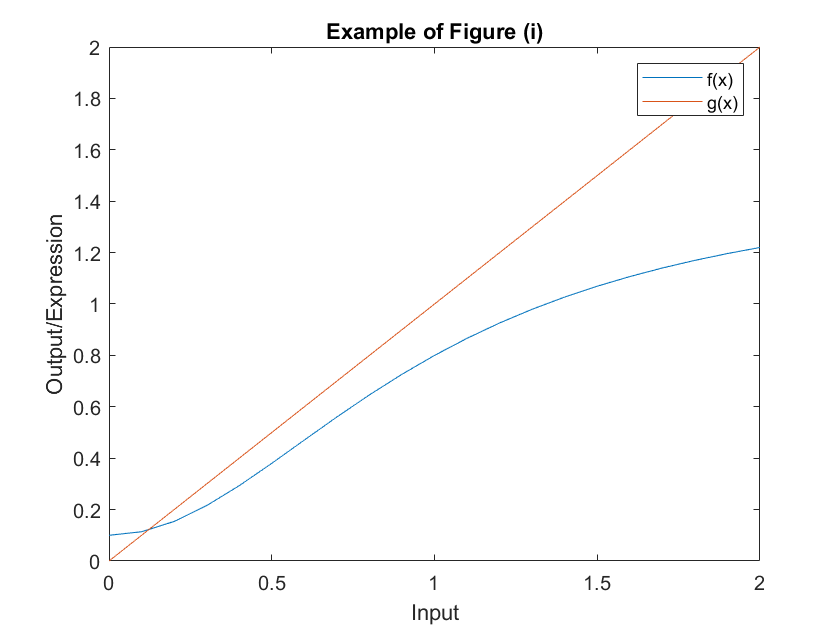

k_prime = 0.1;
beta = 1.5;
x = [0:0.1:2];
f = (k_prime + (beta .* (x .^ 2)))./(1 + (x .^ 2));
g = x;

figure
plot(x,f)
hold on
plot(x,g)
title('Example of Figure (i)')
xlabel('Input')
ylabel('Output/Expression')
legend('f(x)','g(x)')
hold off

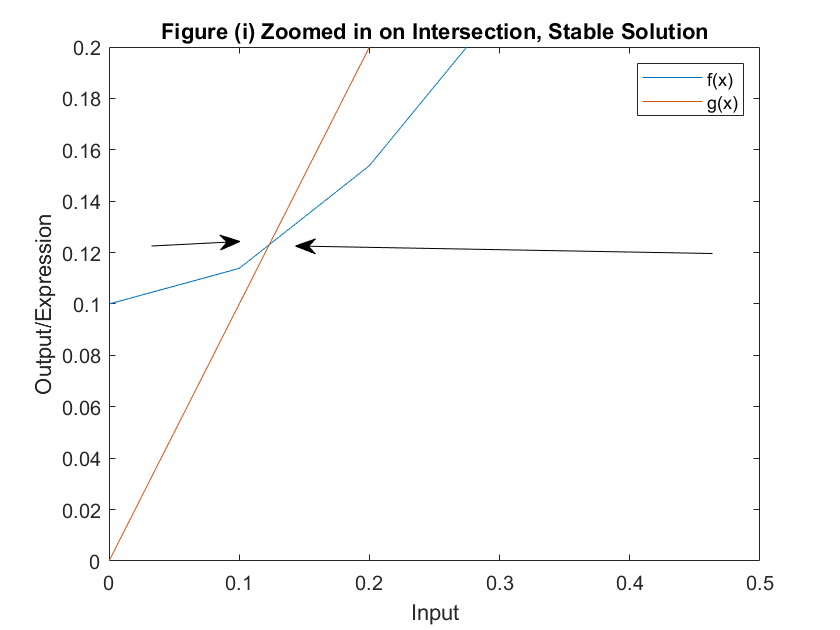

figure
plot(x,f)
hold on
plot(x,g)
title('Figure (i) Zoomed in on Intersection, Stable Solution')
xlabel('Input')
ylabel('Output/Expression')
legend('f(x)','g(x)')
xlim([0,0.5])
ylim([0,0.2])
annotation('arrow',[0.8482 0.3518],[0.5976 0.6095])
annotation('arrow',[0.1804 0.2857],[0.6095 0.6167])
hold off

### Example of figure (iii)

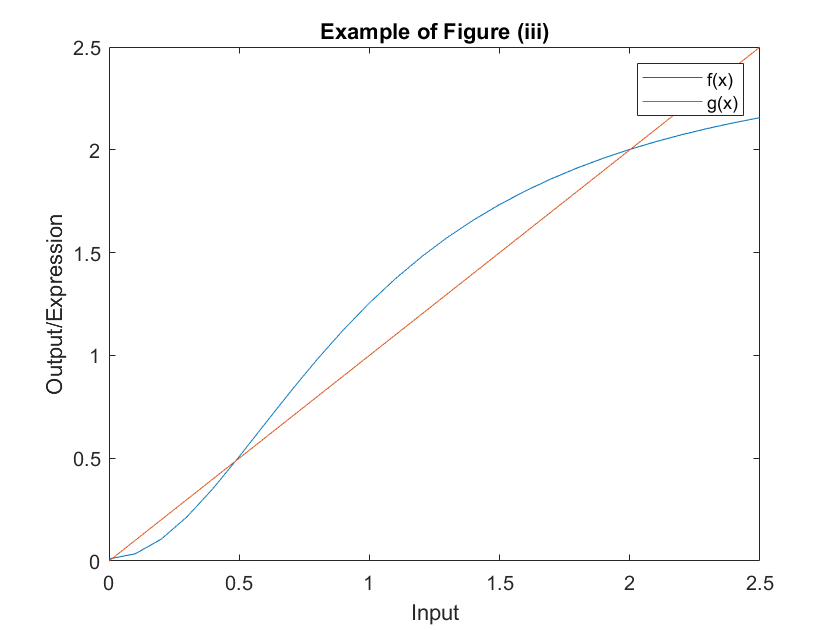

k_prime = 0.01;
beta = 2.5;
x = [0:0.1:2.5];
f = (k_prime + (beta .* (x .^ 2)))./(1 + (x .^ 2));
g = x;

figure
plot(x,f)
hold on
plot(x,g)
title('Example of Figure (iii)')
xlabel('Input')
ylabel('Output/Expression')
legend('f(x)','g(x)')
hold off

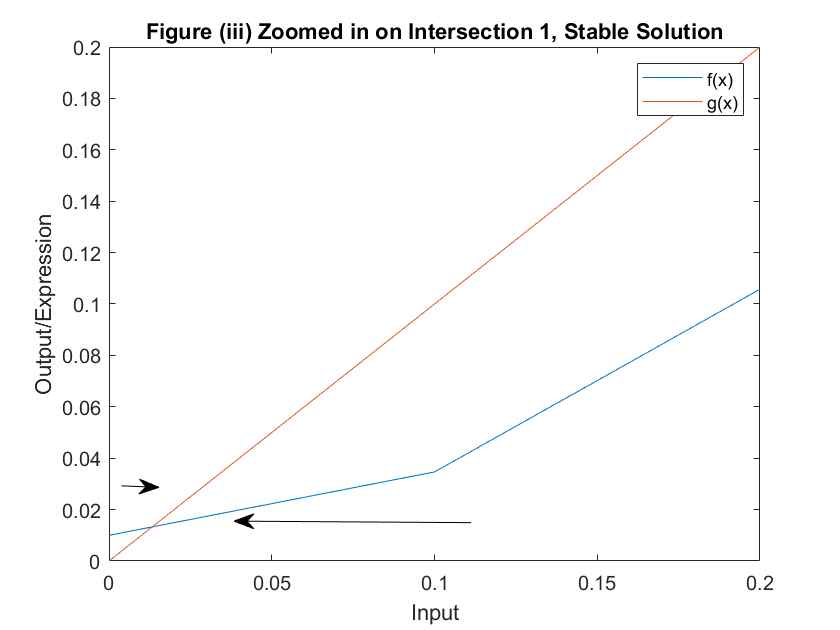

figure
plot(x,f)
hold on
plot(x,g)
title('Figure (iii) Zoomed in on Intersection 1, Stable Solution')
xlabel('Input')
ylabel('Output/Expression')
legend('f(x)','g(x)')
xlim([0,0.2])
ylim([0,0.2])
annotation('arrow',[0.5608 0.2786],[0.1704 0.1728])
annotation('arrow',[0.1447 0.1893],[0.2288 0.2264])
hold off

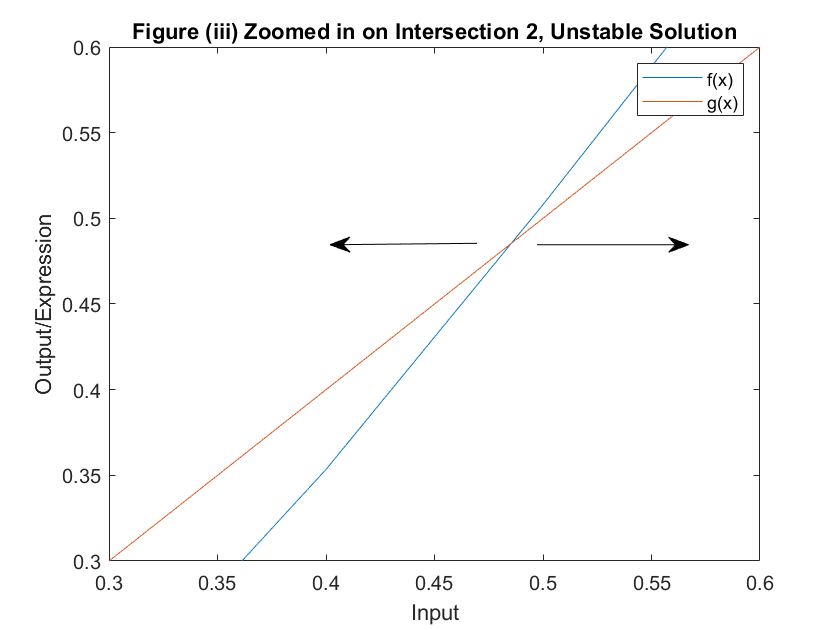

figure
plot(x,f)
hold on
plot(x,g)
title('Figure (iii) Zoomed in on Intersection 2, Unstable Solution')
xlabel('Input')
ylabel('Output/Expression')
legend('f(x)','g(x)')
xlim([0.3, 0.6])
ylim([0.3, 0.6])
annotation('arrow',[0.6393 0.8197],[0.6115 0.6115])
annotation('arrow',[0.5679 0.3929],[0.6138 0.6115])
hold off

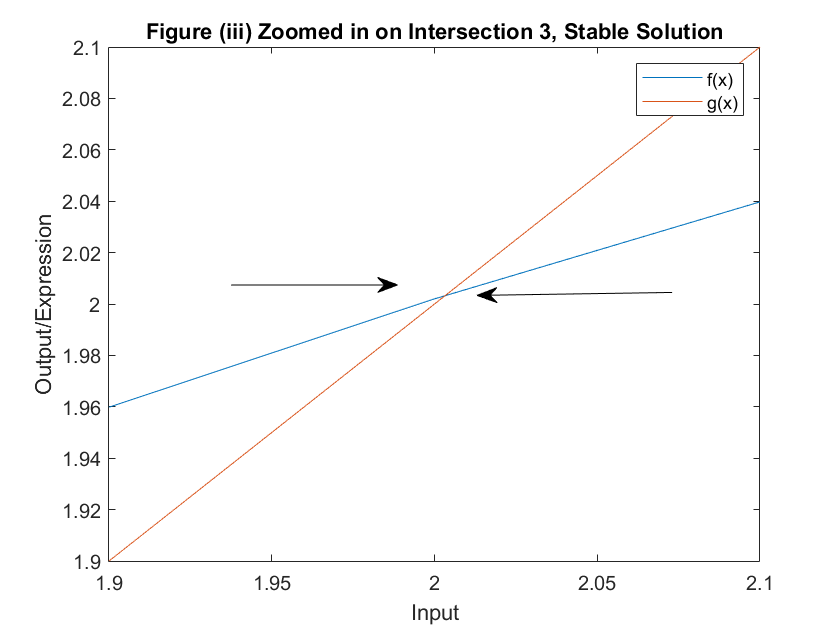


figure
plot(x,f)
hold on
plot(x,g)
title('Figure (iii) Zoomed in on Intersection 3, Stable Solution')
xlabel('Input')
ylabel('Output/Expression')
legend('f(x)','g(x)')
xlim([1.9, 2.1])
ylim([1.9, 2.1])
annotation('arrow',[0.8001 0.5679],[0.5358 0.5311])
annotation('arrow',[0.2751 0.4733],[0.5477 0.5477])
hold off

### Example of figure (v)

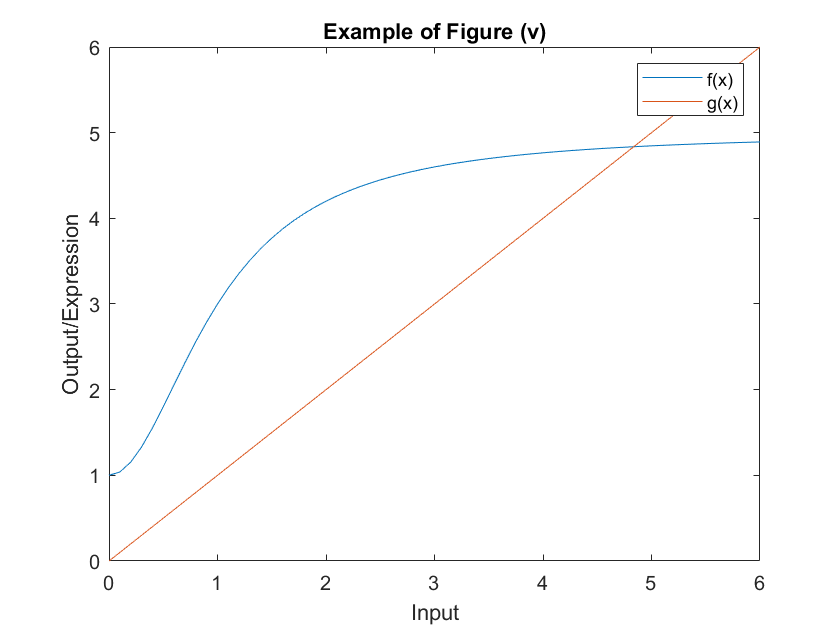

k_prime = 1;
beta = 5;
x = [0:0.1:6];
f = (k_prime + (beta .* (x .^ 2)))./(1 + (x .^ 2));
g = x;

figure
plot(x,f)
hold on
plot(x,g)
title('Example of Figure (v)')
xlabel('Input')
ylabel('Output/Expression')
legend('f(x)','g(x)')
hold off

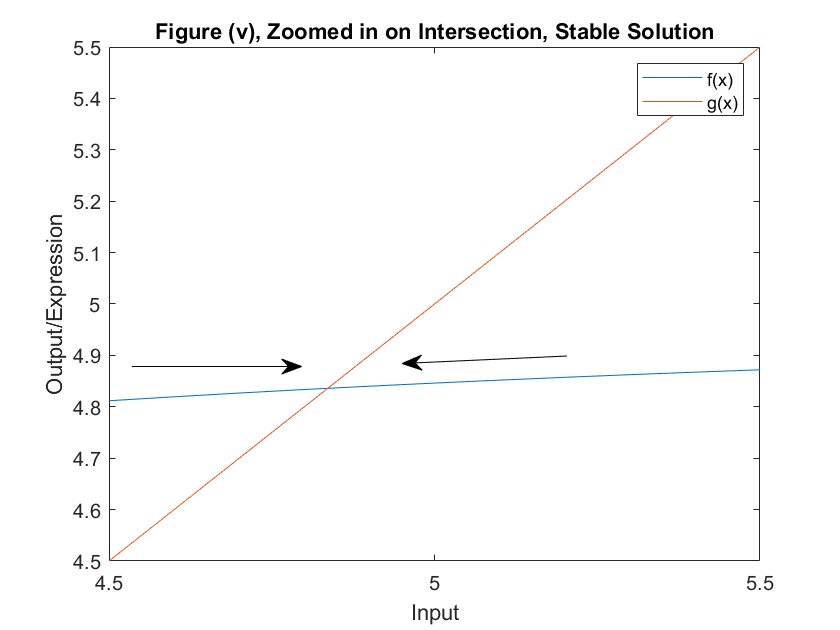

figure
plot(x,f)
hold on
plot(x,g)
title('Figure (v), Zoomed in on Intersection, Stable Solution')
xlabel('Input')
ylabel('Output/Expression')
legend('f(x)','g(x)')
xlim([4.5,5.5])
ylim([4.5,5.5])
annotation('arrow',[0.675 0.4786],[0.4349 0.423])
annotation('arrow',[0.1572 0.359],[0.4182 0.4182])
hold off

## Problem 2

### Part A

gamma = 10;
k_x = 0.1;
beta_x = 4.0;
k_y = 0.0;
beta_y = 2.0;
x = [-5:0.001:5];

f(x,y) = 0


$$0=\gamma \left(k_x +\beta_x \frac{1}{1+y}-x\right)$$



$$0=\;$$

$$k_x +\beta_x \frac{1}{1+y}-x$$



$$x-k_x =\beta_x \frac{1}{1+y}$$



$$\frac{x-k_x }{\beta_x }=\frac{1}{1+y}$$



$$1+y=\frac{\beta_x }{x-k_x }$$



$$y=\;$$

$$\frac{\beta_x }{x-k_x }-1$$


y_fa = beta_x ./ (x - k_x) - 1;

g(x,y) = 0


$$0=k_y +\beta_y x-y$$



$$y=\;$$

$$k_y +\beta_y x$$


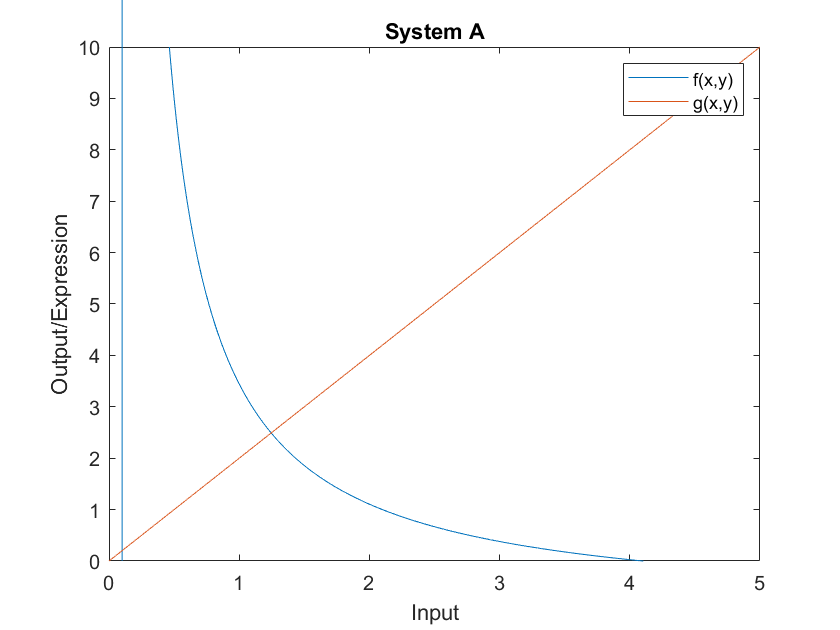

y_ga = k_y + beta_y .* x; 

figure
plot(x,y_fa)
hold on
plot(x,y_ga)
title('System A')
xlabel('Input')
ylabel('Output/Expression')
legend('f(x,y)','g(x,y)')
ylim([0,10])
hold off

f(x,y) = 0


$$0=\gamma \left(k_x +\beta_x \frac{x^2 }{1+x^2 }\frac{1}{1+y}-x\right)$$



$$0=\;$$

$$k_x +\beta_x \frac{x^2 }{1+x^2 }\frac{1}{1+y}-x$$



$$x-k_x =\beta_x \frac{x^2 }{1+x^2 }\frac{1}{1+y}\;$$



$$\frac{x-k_x }{\beta_x }\frac{1+x^2 }{x^2 }=$$

$$\frac{1}{1+y}$$



$$1+y=\frac{\beta_x x^2 }{\left(x-k_x \right)\left(1+x^2 \right)}$$



$$y=\;$$

$$\frac{\beta_x x^2 }{\left(x-k_x \right)\left(1+x^2 \right)}-1$$


y_fb = (beta_x .* x .^2) ./ ((x - k_x) .* (1 + x .^2)) - 1;

g(x,y) = 0


$$0=k_y +\beta_y x-y$$



$$y=k_y +\beta_y x$$


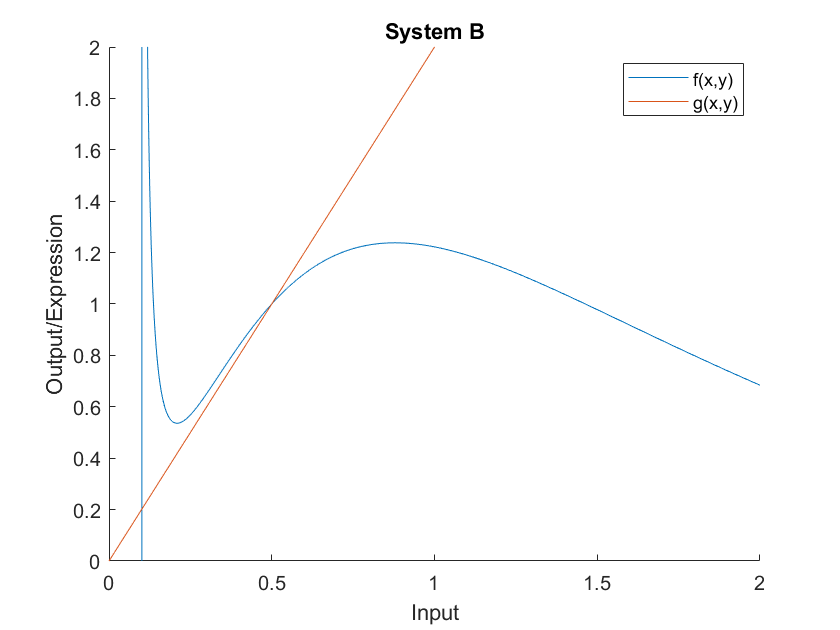

y_gb = k_y + beta_y .* x; 

figure
hold on
plot(x,y_fb)
plot(x,y_gb)
title('System B')
xlabel('Input')
ylabel('Output/Expression')
legend('f(x,y)','g(x,y)')
ylim([0,2])
xlim([0,2])
hold off

### Part B:

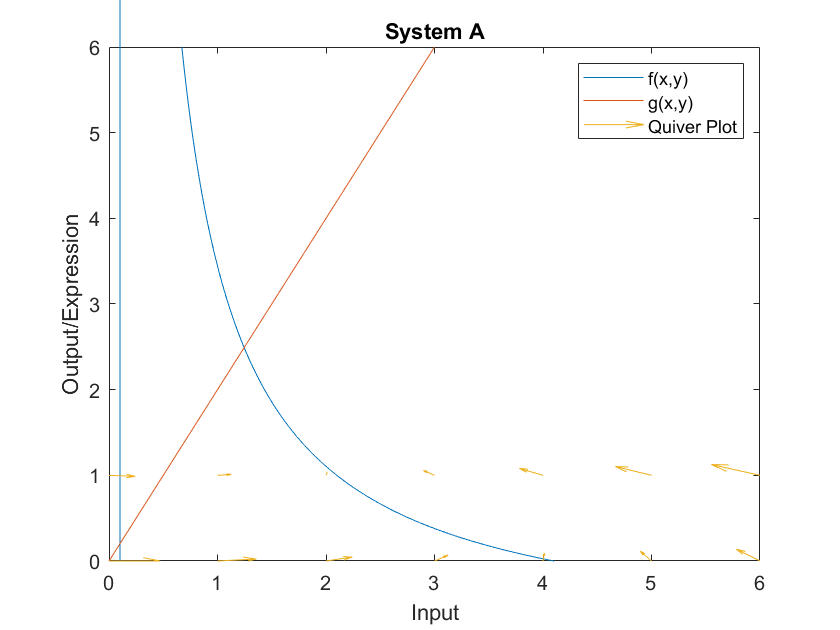

[m,n] = meshgrid(0:1:10,0:1,10);
u = gamma .* (k_x + beta_x ./ (1 + n) - m);
v = k_y + beta_y .* m - n;
figure
plot(x,y_fa)
hold on
plot(x,y_ga)
quiver(m, n, u, v)
title('System A')
xlabel('Input')
ylabel('Output/Expression')
legend('f(x,y)','g(x,y)', 'Quiver Plot')
ylim([0,6])
xlim([0,6])
hold off

The quiver plot arrows all point toward the stationary point, meaning it is stable.

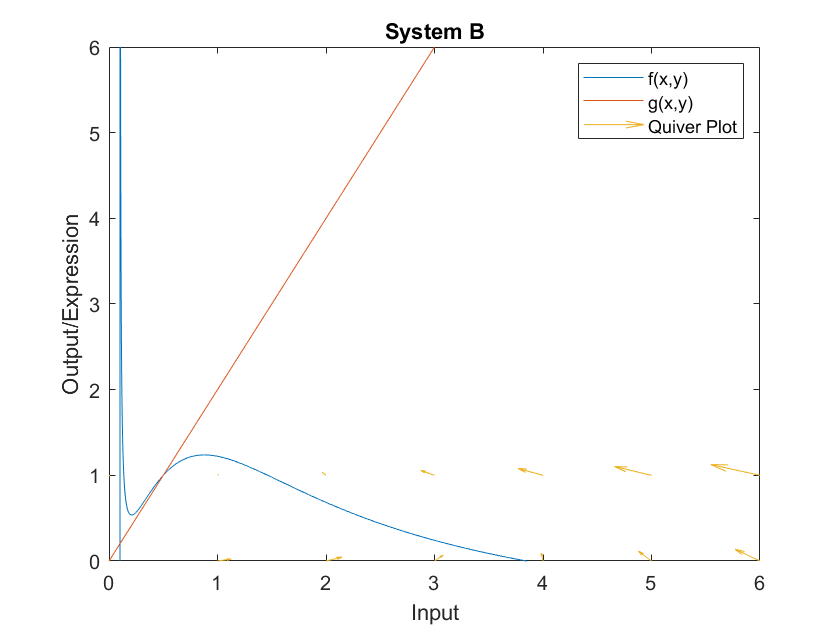

[m,n] = meshgrid(0:1:10,0:1,10);
u = gamma .* (k_x + beta_x .* m .^ 2 ./ ((1 + n) .* (1 + m .^2)) - m);
v = k_y + beta_y .* m - n;
figure
plot(x,y_fb)
hold on
plot(x,y_gb)
quiver(m, n, u, v)
title('System B')
xlabel('Input')
ylabel('Output/Expression')
legend('f(x,y)','g(x,y)', 'Quiver Plot')
ylim([0,6])
xlim([0,6])
hold off

The quiver plot arrows all point toward the stationary point, meaning it is stable.

### Part C:

### Part D:

### Part E:

## Problem 3: 

### Part A:

The given sequence contains the EcoRI recognition sequence: 5' TTCGGA**GAATTC**CGGT 3'. This means that when the restriction enzyme is used to create the BioBrick, the sequence will be cut and the gene will not be properly inserted into your circuit. 

### Part B:

pET vector is part of incompatibility group A and so is pUC. These two vectors will be unstable because they share replication mechanisms. As such, the cell will randomly choose which vector to replicate, but will not replicate both due to the competition of intracellular resources. 

## Problem 4:

GFP:                                             RFP:

5' CTA TAC AAA TAA TAA 3'      5' ATG GCT TCC TCC GAA 3'

3' GAT ATG TTT ATT ATT 5'       3' TAC CGA AGG AGG CTT 5'

Desired:

5' CTA TAC AAA ATG GCT TCC TCC GAA 3'

3' GAT ATG TTT TAC CGA AGG AGG CTT 5'

Add in the BsaI Sequence:

GFP:                                                            RFP:

5' CTA TAC AAA TAA TAA **GAG ACC**3'      5' **GGT CTC **ATG GCT TCC TCC GAA 3'

3' GAT ATG TTT ATT ATT **CTC TGG** 5'      3' **CCA GAG **TAC CGA AGG AGG CTT 5'

Identify the Cut Sites:

GFP:                                                              RFP:

5' CTA TAC AAA T|AA TAA GAG ACC3'      5' GGT CTC A|TG GCT TCC TCC GAA 3'

3' GAT ATG TTT ATT AT|T CTC TGG 5'      3' CCA GAG TAC CG|A AGG AGG CTT 5'

Hybridization: The bolded bases don't match up; We need to change the stop codons in GFP to make sure that the sequences hybridize.

5' CTA TAC AAA T**TG GC**T TCC TCC GAA 3'

3' GAT ATG TTT A**TT AT**A AGG AGG CTT 5'

New sequences and cut sites:

GFP:                                                               RFP:

5' CTA TAC AAA A|TG GCT GAG ACC3'      5' GGT CTC A|TG GCT TCC TCC GAA 3'

3' GAT ATG TTT TAC CG|A CTC TGG 5'      3' CCA GAG TAC CG|A AGG AGG CTT 5'

Hybridization: The sequences will hybridize and they match the desired sequence!

5' CTA TAC AAA ATG GCT TCC TCC GAA 3'

3' GAT ATG TTT TAC CGA AGG AGG CTT 5'

Primers:

**GFP: 5' GGT CTC AGC CAT TTT GTA TAG 3'**

**RFP: 5' GGT CTC ATG GCT TCC TCC GAA 3'**